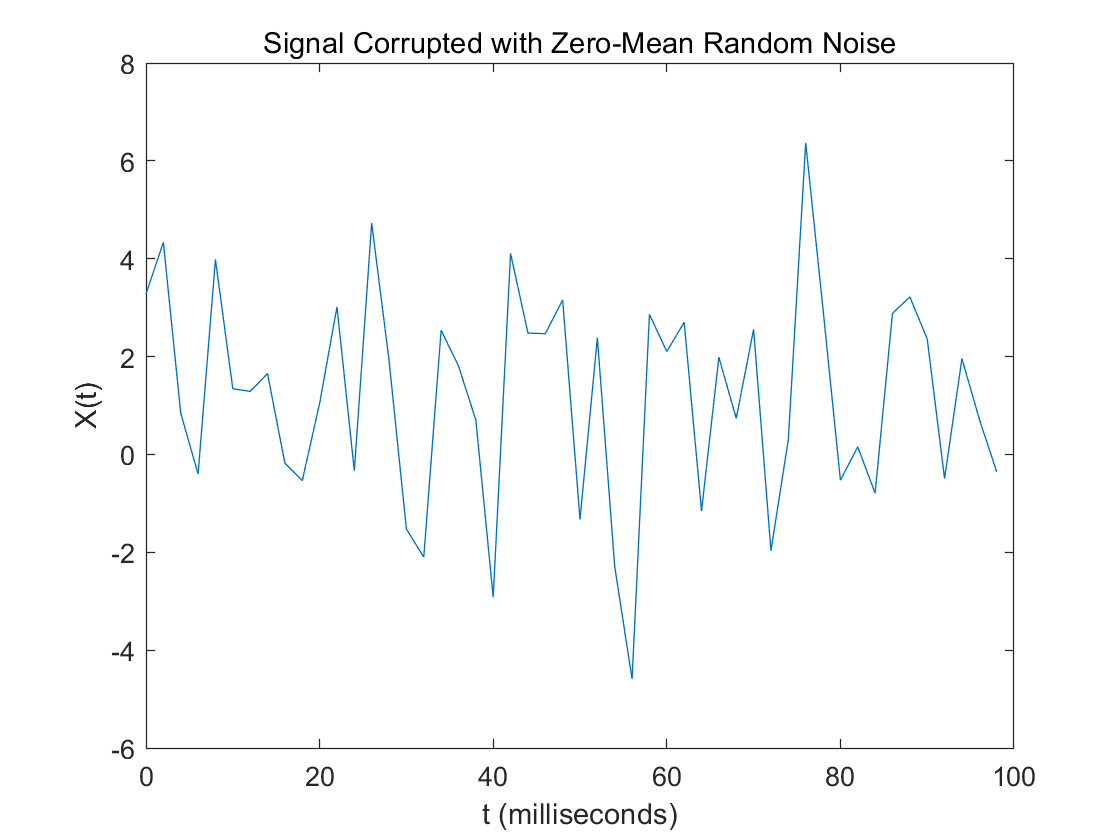

% generate signal
Fs = 500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 6000;             % Length of signal
t = (0:L-1)*T;        % Time vector
S = 1+0.8*sin(2*pi*50*t) + sin(2*pi*120*t);
X = S + 2*randn(size(t));
plot(1000*t(1:50),X(1:50));
title('Signal Corrupted with Zero-Mean Random Noise');
xlabel('t (milliseconds)');ylabel('X(t)');

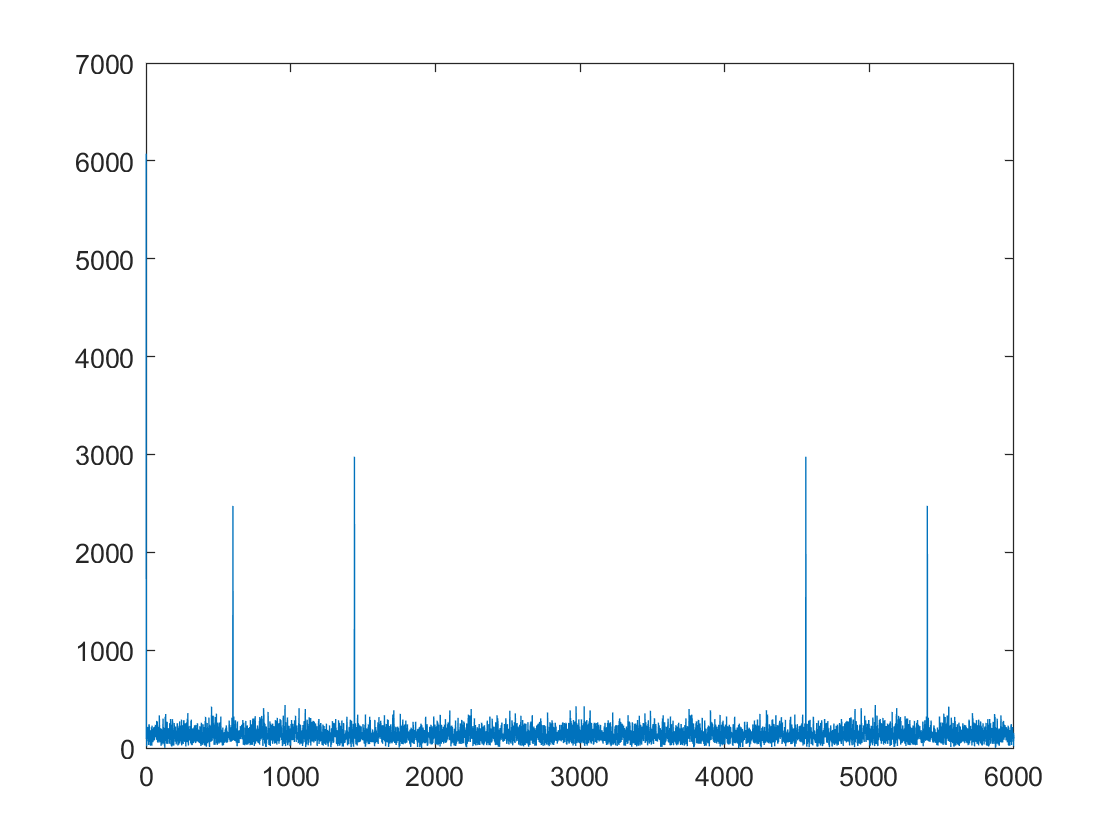

% FFT
Y1 = fft(X);
figure;
plot(abs(Y1));

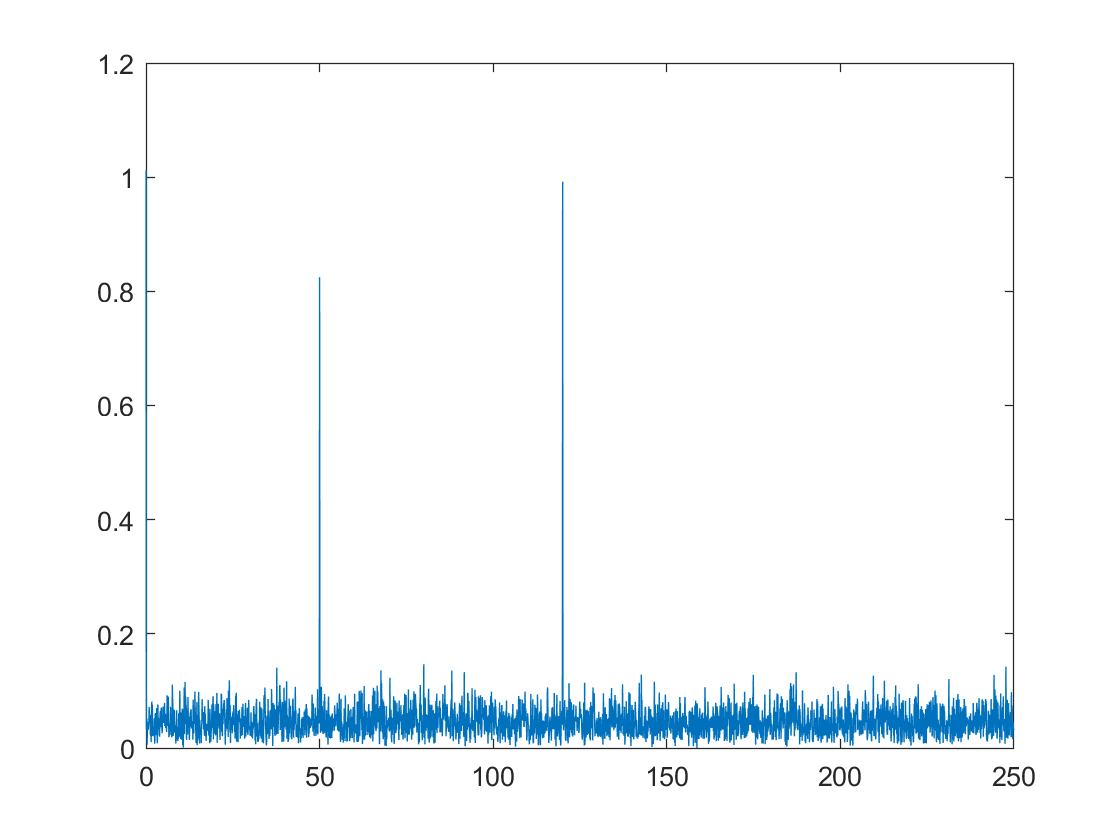

Y1 = fftshift(Y1);
Y1 = Y1(L/2+1:end)/L;
Y1(2:end-1) = Y1(2:end-1)*2;
f = Fs*(0:L/2-1)/L;
%fshift = (-L/2:L/2-1)*(Fs/L);
%Y1=Y1/L;
figure;
plot(f, abs(Y1))

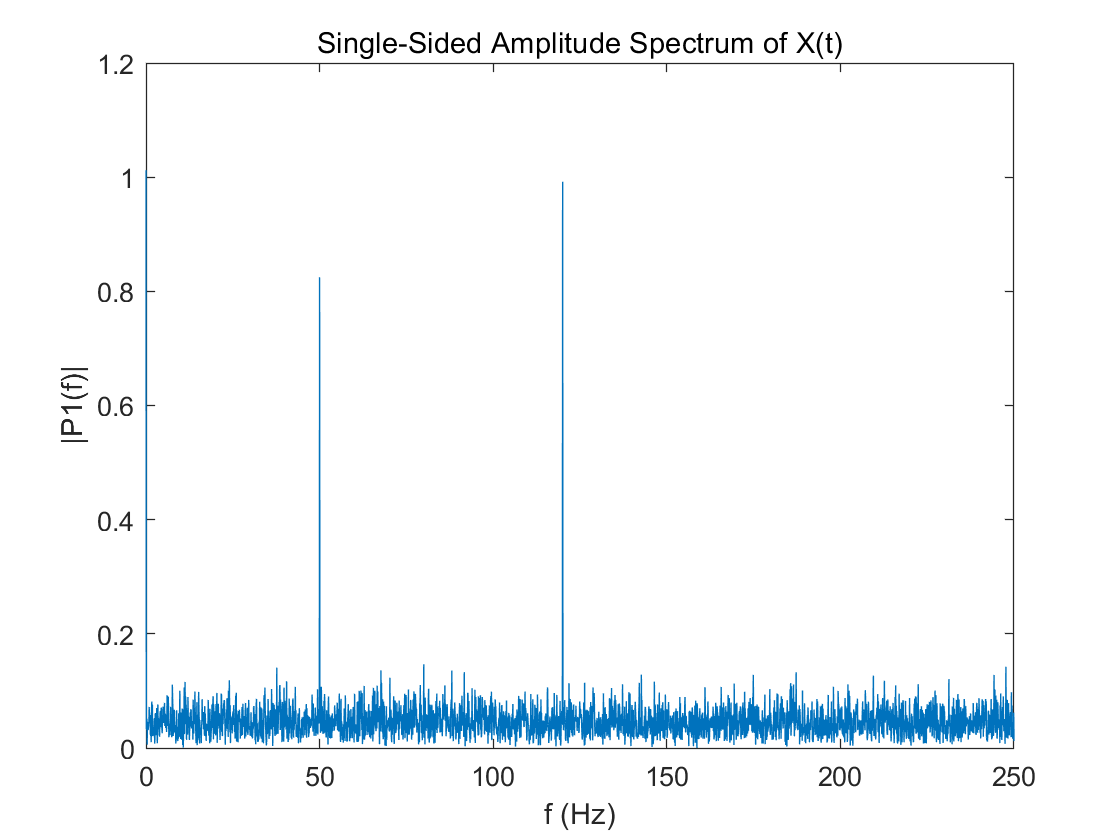

% FFT
Y = fft(X);
P2 = abs(Y/L);		% 求幅值
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
figure
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)');ylabel('|P1(f)|');

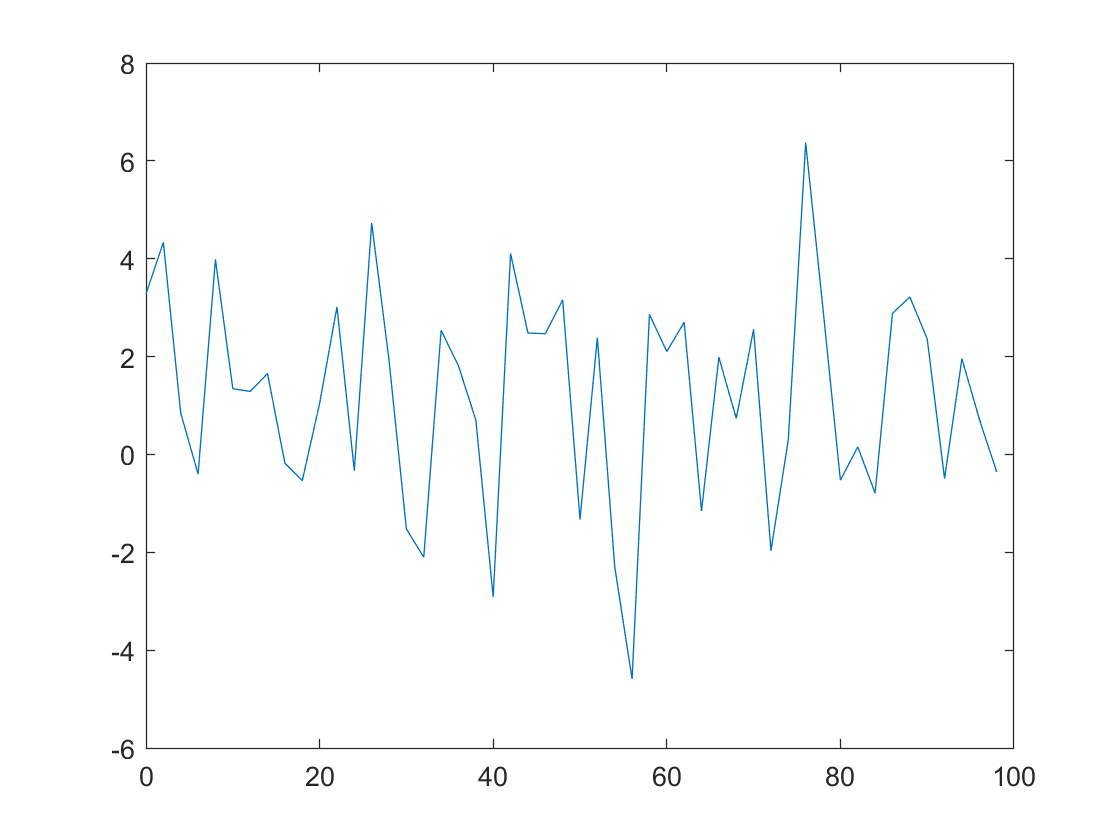

X1 = ifft(Y);
plot(1000*t(1:50),X1(1:50))

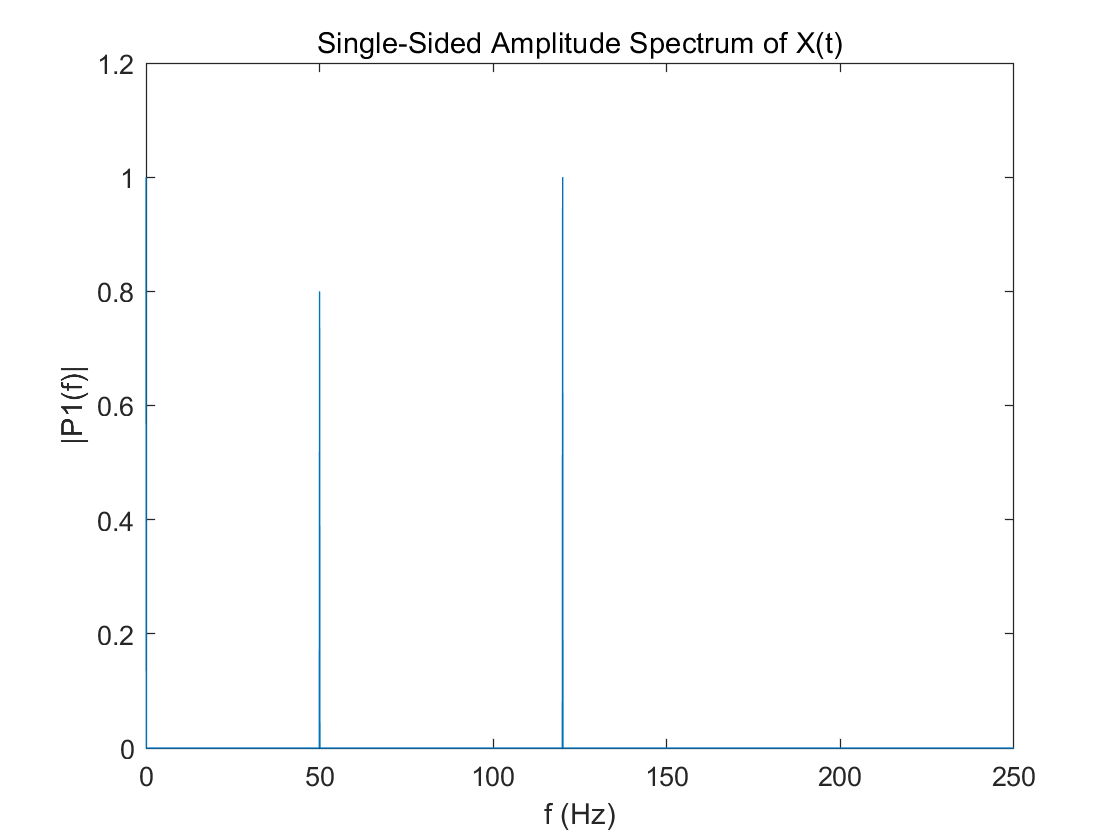

Y = fft(S);
P2 = abs(Y/L);		% 求幅值
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
figure
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)');ylabel('|P1(f)|');